g = @(x,y) exp(x.^2./2+ y.^2/2);
f = @(x,y) (1 + x.^2 +y.^2) .* exp(x.^2+y.^2);
g = @(x,y) g_C1(x,y);
f = @(x,y) f_C1(x,y);
N = 2^6;
%U = generate_intial_guess(f,g,N,N);
U=refine_interpolation(U_init,N/2,N);
h=1/N;
alpha=4/5;
beta=2/5;
tau = 0.8;
delta = h^alpha;
theta = 0.7*h^beta;
[V,TU] = T_epsilon_accurate_operator(U,N,delta,theta);
[central_difference1,central_difference2] = two_scale_central_difference_accurate(U,N,V,delta);
[U,error0]=newton_increment_accurate(U,N,delta,theta,f,tau);
ite=1;
fprintf('iteration number:');

iteration number:

disp(ite);

     1



fprintf('error:');

error:

disp(error0);

    2.4919



while 1
    [U,error]=newton_increment_accurate(U,N,delta,theta,f,tau);
    ite=ite+1;
    if mod(ite,2)==0
        fprintf('iteration number:');
        disp(ite);
        fprintf('error:');
        disp(error);
    end
    if error<1e-8*error0
        break
    end
end

iteration number:

     2



error:

    0.6001



iteration number:

     4



error:

    0.0490



iteration number:

     6



error:

    0.0065



iteration number:

     8



error:

   7.0698e-04



iteration number:

    10



error:

   3.6397e-05



iteration number:

    12



error:

   6.4562e-06



iteration number:

    14



error:

   2.5825e-07



iteration number:

    16



error:

   1.0330e-08



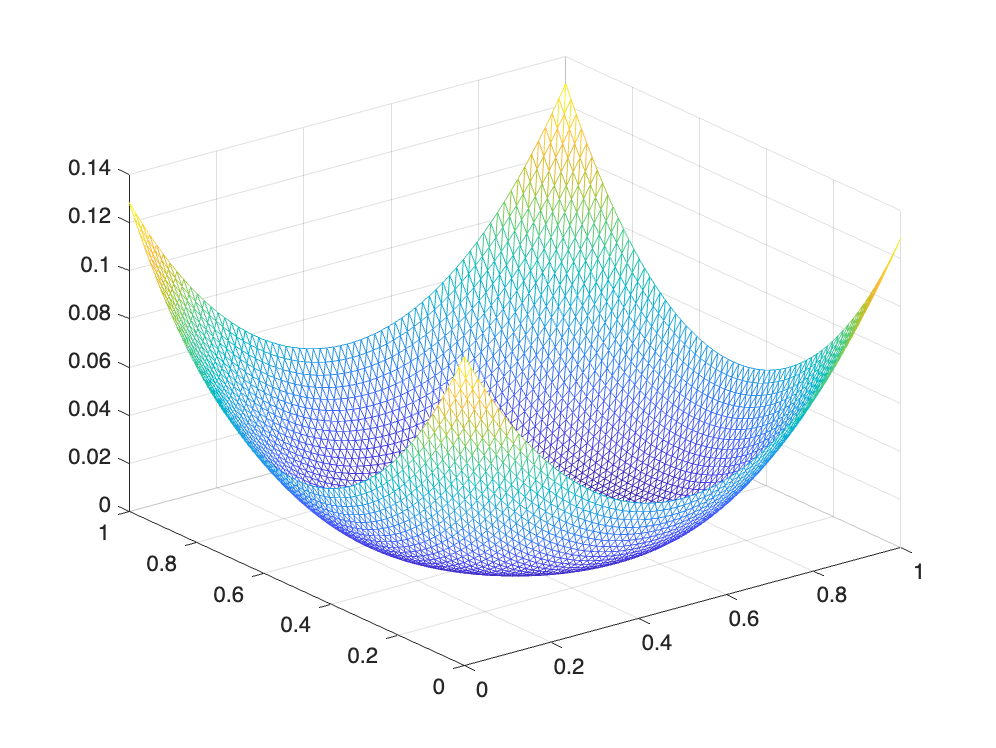

U0=zeros(N+1,N+1);
for i=1:N+1
    for j=1:N+1
        U0(i,j) = g((j-1)*h,(i-1)*h);
    end
end
L_infty_error = max(max(abs(U0-U)));
L_2_error = sqrt(norm(U0-U,2)^2*h^2);
[X,Y]= meshgrid(0:h:1,0:h:1);
T=zeros(N^2*2,3);
node=0;
for i=1:N
    for j=1:N
        node=node+1;
        T(node,1)=j+(N+1)*(i-1);
        T(node,2)=j+(N+1)*(i-1)+1;
        T(node,3)=j+(N+1)*(i-1)+1+N+1;
        node=node+1;
        T(node,1)=j+(N+1)*(i-1);
        T(node,2)=j+(N+1)*(i-1)+N+1;
        T(node,3)=j+(N+1)*(i-1)+1+N+1;
    end
end
trimesh(T,X,Y,U);

fprintf('iteration number:');

iteration number:

disp(ite);

    16



fprintf('L infty error');

L infty error

disp(L_infty_error);

   1.2722e-04



U_init = U;